案例1 

 opt

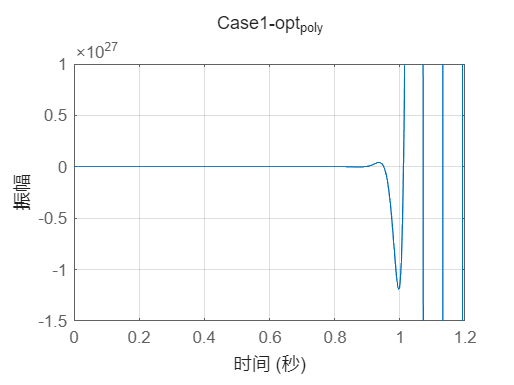

num = [1 50 -100 200];  % 多个右半平面零点
denum = [1 -10 100 -500 1000];  % 多个右半平面极点
Plant = tf(num,denum);
Q2 = opt_poly(Plant);
[C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case1-opt_{poly}");
grid on;

pid


ans =
 
  Kp = 1
 
纯 P 控制器。
模型属性


mine

num = [1 50 -100 200];  % 多个右半平面零点
denum = [1 -10 100 -500 1000];  % 多个右半平面极点
Plant = tf(num,denum);
Q2 = TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


[C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case1-opt_{poly}");
grid on;

案例2

opt

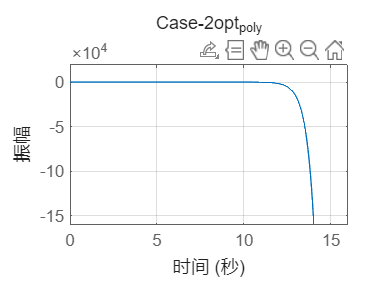

num = [1e-3 1 -1e2 1e3];  % 极端数值
denum = [1 0.001 1e2 0 0];  % 非常小的阻尼+双重积分
Plant = tf(num,denum);
Q2 = opt_poly(Plant);
[C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-2opt_{poly}");
grid on;

mine

num = [1e-3 1 -1e2 1e3];  % 极端数值
denum = [1 0.001 1e2 0 0];  % 非常小的阻尼+双重积分
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


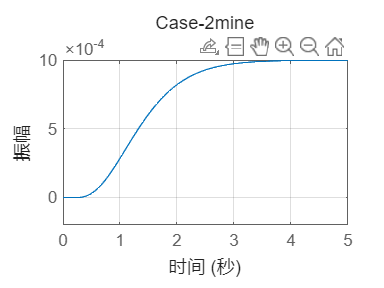

[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-2mine")
grid on;

案例3 

opt

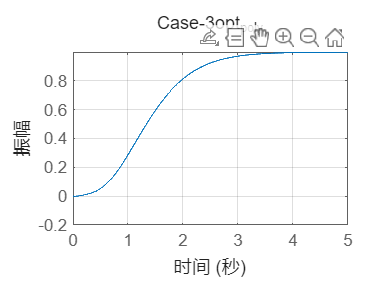

num = [1 -20 100 -1000];  % 多个不稳定零点
denum = [1 5 0 0 0];  % 三重积分器
Plant = tf(num,denum);
Q2 = opt_poly(Plant);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-3opt_{poly}");
grid on;

mine

num = [1 -20 100 -1000];  % 多个不稳定零点
denum = [1 5 0 0 0];  % 三重积分器
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


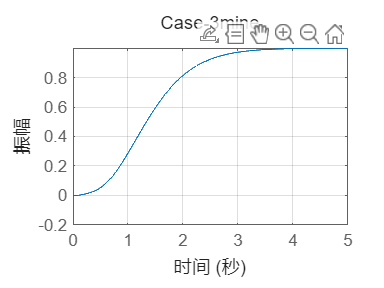

[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-3mine")
grid on;

案例4 

opt

num = [1 -20 100 -1000];  % 多个不稳定零点
denum = [1 5 0 0 0];  % 三重积分器
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


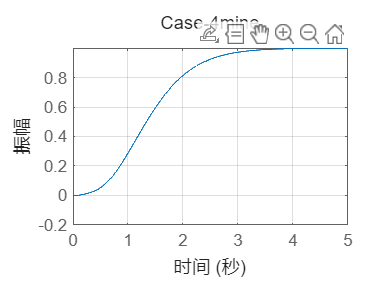

[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-4mine")
grid on;

mine

num = [1 -20 100 -1000];  % 多个不稳定零点
denum = [1 5 0 0 0];  % 三重积分器
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-4mine")
grid on;

案例5 

opt

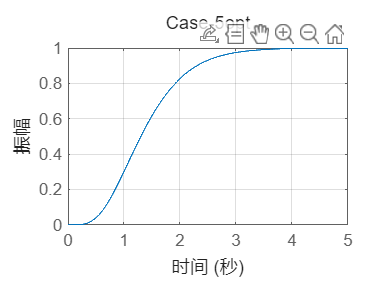

num = [1 -30 400];  % 不稳定零点
denum = [1 0.1 10000 0 0];  % 高频振荡+双重积分
Plant = tf(num,denum);
Q2=opt_poly(Plant);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-5opt")
grid on;

mine

num = [1 -30 400];  % 不稳定零点
denum = [1 0.1 10000 0 0];  % 高频振荡+双重积分
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


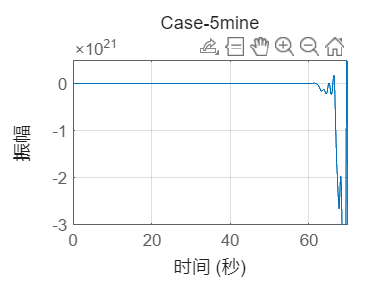

[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-5mine")
grid on;

案例6 

opt

num = [1 -15 50];  % 2阶不稳定零点
denum = [1 0 0 0 0 0];  % 4重积分器（相对阶=2）
Plant = tf(num,denum);
Q2=opt_poly(Plant);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);

调整后的alphas: [3 3 3 3 5]


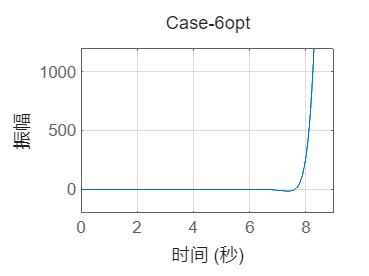

T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-6opt")
grid on;

mine

num = [1 -15 50];  % 2阶不稳定零点
denum = [1 0 0 0 0 0];  % 4重积分器（相对阶=2）
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);

调整后的alphas: [3 3 3 3 5]


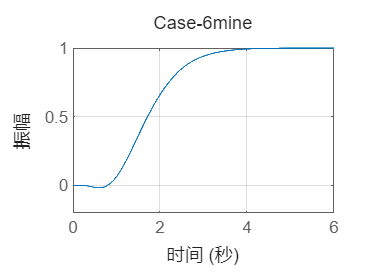

T = giveTransferFunction(C1,C2,Plant);
step(T)
title("Case-6mine")
grid on;